# Lab  3 - Bildkvalitet

## 1. Color Gamut

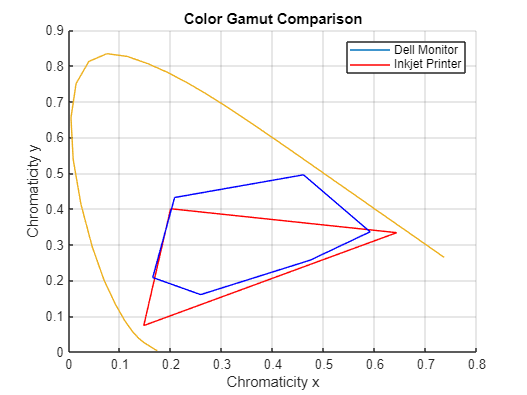

% Load the CIEXYZ data for the devices
load('Dell.mat'); % Load Dell monitor primaries
load('Inkjet.mat'); % Load Inkjet printer primaries

% Plot color gamut
figure;
hold on;
plot_chrom(XYZdell, 'r'); % Red for Dell
plot_chrom(XYZinkjet, 'b'); % Blue for Inkjet
hold off;
title('Color Gamut Comparison');
xlabel('Chromaticity x');
ylabel('Chromaticity y');
legend('Dell Monitor', 'Inkjet Printer');
grid on;


% Answer: The Dell monitor is clearly better for more yellow/lighter orange colors
% as the Inkjeet printer is a bit licking in that area. The Inkjet printer
% is better in darker blues/purples and also intense red. 
%
% You should use thee Dell monitor for higher y-chromaticity values and the Inkjet printer for lower.


## 2. Mathematical metrics

Only compares the intensity of the distorsions.

### 2.1 Grayscale image (MSE/SNR)

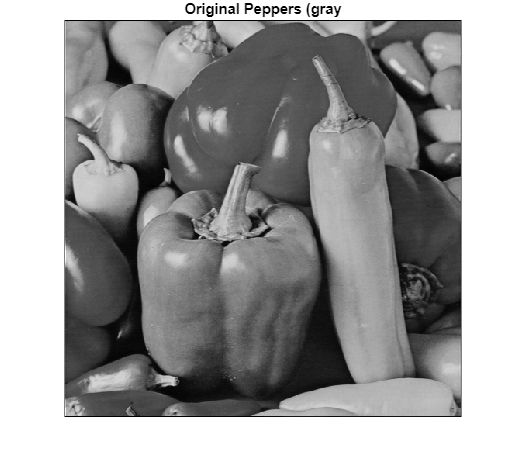

% Load grayscale image
peppers_gray = im2double(imread('peppers_gray.tif'));

% 2.1.1 Interpolation

% Resize using different interpolation methods (reproductions)
img_nearest = imresize(imresize(peppers_gray, 0.25, 'nearest'), 4, 'nearest');
img_bilinear = imresize(imresize(peppers_gray, 0.25, 'bilinear'), 4, 'bilinear');
img_bicubic = imresize(imresize(peppers_gray, 0.25, 'bicubic'), 4, 'bicubic');

% Calculate MSE (compare reproduction vs reproduction)
mse_nearest = immse(img_nearest, peppers_gray);
mse_bilinear = immse(img_bilinear, peppers_gray);
mse_bicubic = immse(img_bicubic, peppers_gray);

% Calculate SNR (compare reproduction vs reproduction)
snr_nearest = snr(double(peppers_gray), double(peppers_gray - img_nearest));
snr_bilinear = snr(double(peppers_gray), double(peppers_gray - img_bilinear));
snr_bicubic = snr(double(peppers_gray), double(peppers_gray - img_bicubic));

% Print comparisons
figure
imshow(peppers_gray)
title('Original Peppers (gray')

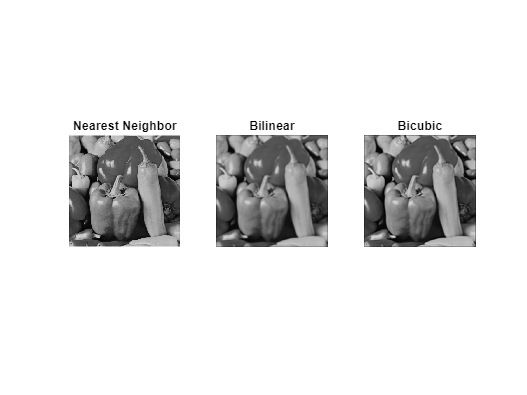


% Display images
figure
subplot(1,3,1);
imshow(img_nearest)
title('Nearest Neighbor')
subplot(1,3,2);
imshow(img_bilinear)
title('Bilinear')
subplot(1,3,3);
imshow(img_bicubic)
title('Bicubic')


% Display results of MSE and SNR
fprintf('(Nearest) MSE: %f, SNR: %f\n', mse_nearest, snr_nearest);

(Nearest) MSE: 0.004300, SNR: 17.095612


fprintf('(Bilinear) MSE: %f, SNR: %f\n', mse_bilinear, snr_bilinear);

(Bilinear) MSE: 0.002843, SNR: 18.892184


fprintf('(Bicubic) MSE: %f, SNR: %f\n', mse_bicubic, snr_bicubic);

(Bicubic) MSE: 0.002279, SNR: 19.853756



% Anwser: 
% According to MSE, the ranking is: Nearest, Bilinear & Bicubic
% According to SNR, the ranking is: Bicubic, Bilinear & Nearest
% According to me, the ranking is: Bicubic, Biliner & Nearest

% 2.1.2 Halftoning

% Thresholding
img_threshold = double(peppers_gray >= 0.5);

% Error diffusion using dither
img_dither = double(dither(peppers_gray));

% Calculate MSE for halftoned images
mse_threshold = immse(img_threshold, peppers_gray);
mse_dither = immse(img_dither, peppers_gray);

% Calculate SNR for halftoned images
snr_threshold = snr(double(peppers_gray), double(peppers_gray - img_threshold));
snr_dither = snr(double(peppers_gray), double(peppers_gray - img_dither));

% Display images
figure
imshow(peppers_gray)
title('Original Peppers (gray')

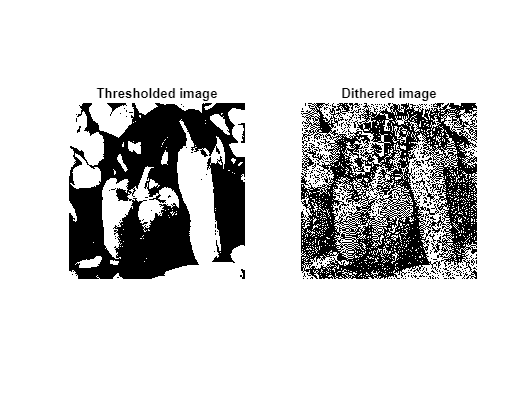


figure
subplot(1,2,1);
imshow(img_threshold)
title('Thresholded image')
subplot(1,2,2);
imshow(img_dither)
title('Dithered image')


% Display results of MSE and SNR
fprintf('(Threshold) MSE: %f, SNR: %f\n', mse_threshold, snr_threshold);

(Threshold) MSE: 0.111127, SNR: 2.972086


fprintf('(Dither) MSE: %f, SNR: %f\n', mse_dither, snr_dither);

(Dither) MSE: 0.200404, SNR: 0.411213



% Anwser: 
% According to MSE, the ranking is: Dither over Threshold
% According to SNR, the ranking is: Dither over Threshold
% According to me, the ranking is: Dither over Threshold (because we
% compare similarity, not visual appeal)


### 2.2 Color Image (remove dublication code fix)

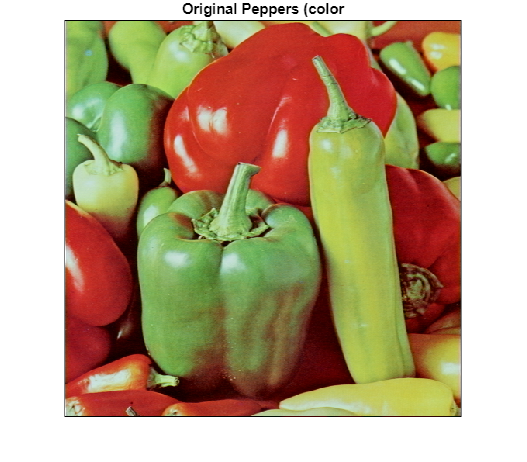

% Load color image
img_color = im2double(imread('peppers_color.tif'));

% Convert to Lab color space (for comparison)
img_Lab = rgb2lab(img_color);

% Thresholding---

% Thresholding each channel separately
r_threshold = double(img_color(:,:,1) >= 0.5);
g_threshold = double(img_color(:,:,2) >= 0.5);
b_threshold = double(img_color(:,:,3) >= 0.5);

% Merge channels back for thresholded image
img_threshold_RGB = cat(3, r_threshold, g_threshold, b_threshold);

% Convert thresholded image to Lab
img_threshold_Lab = rgb2lab(img_threshold_RGB);


% Halftoning---

% Halftone each channel separately
r_halftone = double(dither(img_color(:,:,1)));
g_halftone = double(dither(img_color(:,:,2)));
b_halftone = double(dither(img_color(:,:,3)));

% Merge channels back
img_halftone = cat(3, r_halftone, g_halftone, b_halftone);

% Convert halftone image to Lab
img_halftone_Lab = rgb2lab(img_halftone);


% Comparison---

% Display images
figure
imshow(img_color)   % Original
title('Original Peppers (color')

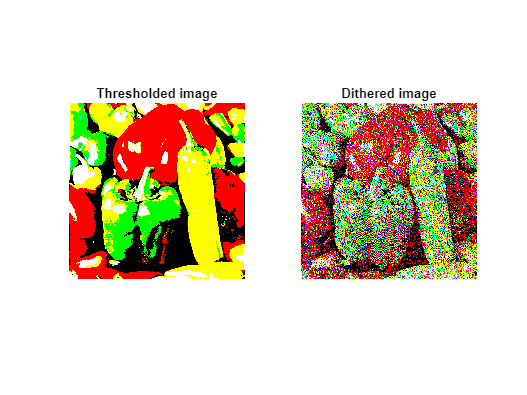


figure
subplot(1,2,1);
imshow(img_threshold_RGB)
title('Thresholded image')
subplot(1,2,2);
imshow(img_halftone)
title('Dithered image')


% Compute delta Eab
delta_eab_threshold = sqrt(sum((img_Lab - img_threshold_Lab).^2, 3));
avg_delta_eab_threshold = mean(delta_eab_threshold(:));

delta_eab_halftone = sqrt(sum((img_Lab - img_halftone_Lab).^2, 3));
avg_delta_eab_halftone = mean(delta_eab_halftone(:));

% Display delta Eab result
fprintf('Average delta Eab threshold: %f\n', avg_delta_eab_threshold);

Average delta Eab threshold: 50.157710


fprintf('Average delta Eab halftoning: %f\n', avg_delta_eab_halftone);

Average delta Eab halftoning: 72.842270



% Anwser: 
% According to delta Eab, the ranking is: Threshold over halftoning
% According to me, the ranking is: Threshold over halftoning
% Maybe should be applied to both in 2.2 instead of original image (fix??)

## 3. Mathematical metrics involving HVS

Same class as before

% Load grayscale image % Redo of 2.1.2 (fix)
peppers_gray = im2double(imread('peppers_gray.tif'));

% Part 1 HVS-based SNR on Halftoned Images---
% Apply thresholding for halftoning
img_threshold = double(peppers_gray >= 0.5);

% Apply dithering for halftoning
img_dither = double(dither(peppers_gray));

% Compute HVS-based SNR using provided function snr_filter
snr_threshold_HVS = snr_filter(peppers_gray, peppers_gray - img_threshold);
snr_dither_HVS = snr_filter(peppers_gray, peppers_gray - img_dither);

% Display results
fprintf('(HVS-based SNR - Thresholding): %f\n', snr_threshold_HVS);

(HVS-based SNR - Thresholding): 3.348770


fprintf('(HVS-based SNR - Dithering): %f\n', snr_dither_HVS);

(HVS-based SNR - Dithering): 13.322967



% Anwser: 
% According to HSV model (SNR-filter), the ranking is: Halftoning and
% Thresholding
% According to me, the ranking is: Dither over Threshold (because we
% compare similarity, not visual appeal)


% Part 2 HVS-based DEab Metric on Color Images---

% Load color image
img_color = im2double(imread('peppers_color.tif'));

% Define parameters for MFTsp function
N = 21;       % Filter size (adjust based on experiment)
d = 0.0847;   % Dot size for 300 dpi
dis = 500;    % Viewing distance in mm

% Get MTF filter from MFTsp function
hvs_filter = MFTsp(N, d, dis);  % Returns an matrix

% Apply filtering using convolution (separately to each channel)
R_filtered = imfilter(img_color(:,:,1), hvs_filter, 'same');
G_filtered = imfilter(img_color(:,:,2), hvs_filter, 'same');
B_filtered = imfilter(img_color(:,:,3), hvs_filter, 'same');

% Ensure no negative values before conversion
R_filtered = max(R_filtered, 0);
G_filtered = max(G_filtered, 0);
B_filtered = max(B_filtered, 0);

% Merge the filtered RGB channels
img_filtered = cat(3, R_filtered, G_filtered, B_filtered);

% Convert to Lab color space
img_Lab_original = rgb2lab(img_color);
img_Lab_filtered = rgb2lab(img_filtered);

% Compute Delta Eab with HVS filtering
delta_eab_HVS = sqrt(sum((img_Lab_original - img_Lab_filtered).^2, 3));
avg_delta_eab_HVS = mean(delta_eab_HVS(:));

% Display result
fprintf('HVS delta Eab Metric: %f\n', avg_delta_eab_HVS);

HVS delta Eab Metric: 1.077599


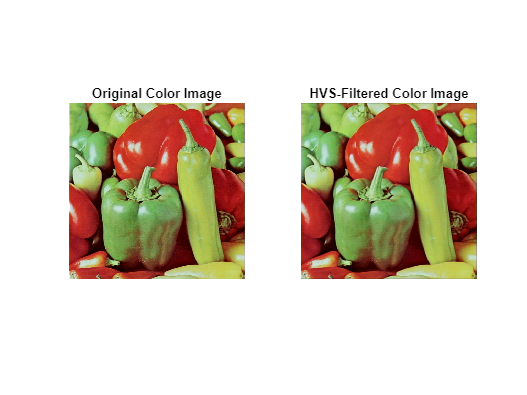


% Show original and filtered images
figure;
subplot(1,2,1);
imshow(img_color);
title('Original Color Image');
subplot(1,2,2);
imshow(img_filtered);
title('HVS-Filtered Color Image');



% Answer: Since there is a small diffrence and the images look almost
% identical I would say its good. 


## Chapter 4 S-CIELab Quality Metric

Takes into account the visibility of distortions.

### 4.1 S-CIELab as a Full-Reference Metric

% Downsample and upsample using different interpolation methods (like ch 1)
img_nearest = imresize(imresize(img_color, 0.25, 'nearest'), 4, 'nearest');
img_bilinear = imresize(imresize(img_color, 0.25, 'bilinear'), 4, 'bilinear');
img_bicubic = imresize(imresize(img_color, 0.25, 'bicubic'), 4, 'bicubic');

% Convert images to CIEXYZ color space
img_xyz_original = rgb2xyz(img_color);
img_xyz_nearest = rgb2xyz(img_nearest);
img_xyz_bilinear = rgb2xyz(img_bilinear);
img_xyz_bicubic = rgb2xyz(img_bicubic);

% Define white point for CIED65
white_point = [95.05, 100, 108.9];

% Compute S-CIELab metric
sampPerDeg = 30; % Example value, adjust based on resolution and viewing distance
scielab_nearest = scielab(sampPerDeg, img_xyz_original, img_xyz_nearest, white_point, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


scielab_bilinear = scielab(sampPerDeg, img_xyz_original, img_xyz_bilinear, white_point, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


scielab_bicubic = scielab(sampPerDeg, img_xyz_original, img_xyz_bicubic, white_point, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


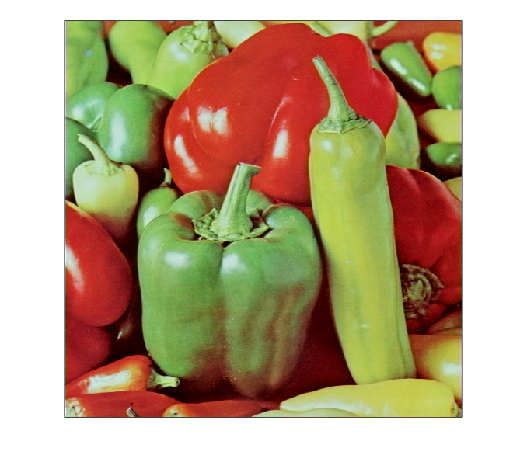


% Compute average S-CIELab difference
avg_scielab_nearest = mean(scielab_nearest(:));
avg_scielab_bilinear = mean(scielab_bilinear(:));
avg_scielab_bicubic = mean(scielab_bicubic(:));

% Display images
figure
imshow(img_color)   % Original
title('Original Peppers (color')

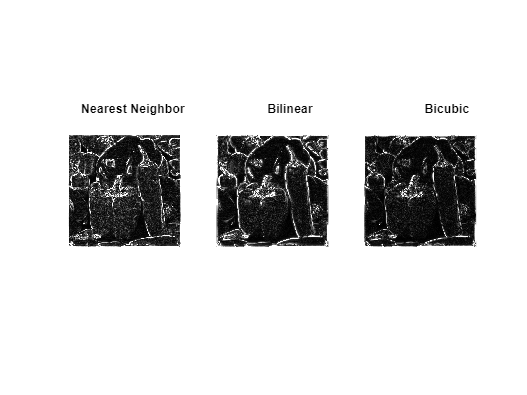


figure
subplot(1,3,1);
imshow(scielab_nearest)
title('Nearest Neighbor')
subplot(1,3,2);
imshow(scielab_bilinear)
title('Bilinear')
subplot(1,3,3);
imshow(scielab_bicubic)
title('Bicubic')


% Display results
figure
fprintf('(Nearest) S-CIELab: %f\n', avg_scielab_nearest);

(Nearest) S-CIELab: 0.230997


fprintf('(Bilinear) S-CIELab: %f\n', avg_scielab_bilinear);

(Bilinear) S-CIELab: 0.237646


fprintf('(Bicubic)S-CIELab: %f\n', avg_scielab_bicubic);

(Bicubic)S-CIELab: 0.166881



% Lower is better
% Answer: 
% According to S-CIELab the ranking is: Bicubic, Nearest and Bilinear
% According to me, the ranking is: Bilinear, Bicubic and Nearest

### 4.2 S-CIELab as a No-Reference Metric

% Load halftone patches
load('colorhalftones.mat');

% Convert halftones to CIEXYZ space
xyz_c1 = rgb2xyz(c1);
xyz_c2 = rgb2xyz(c2);
xyz_c3 = rgb2xyz(c3);
xyz_c4 = rgb2xyz(c4);
xyz_c5 = rgb2xyz(c5);

% Compute S-CIELab metric
scielab_c1 = scielab(sampPerDeg, xyz_c1);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scielab_c2 = scielab(sampPerDeg, xyz_c2);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scielab_c3 = scielab(sampPerDeg, xyz_c3);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scielab_c4 = scielab(sampPerDeg, xyz_c4);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scielab_c5 = scielab(sampPerDeg, xyz_c5);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


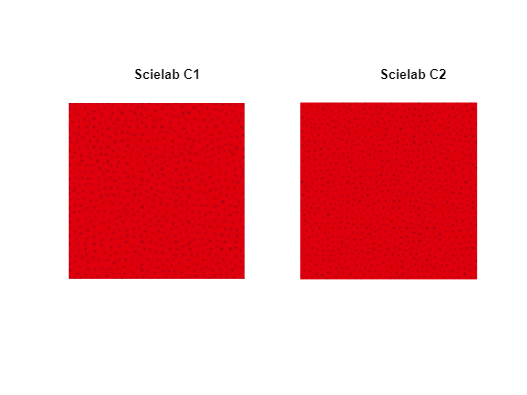


% Compute standard deviation sum as a graininess measure
graininess_c1 = sum([std2(scielab_c1(:,:,1)), std2(scielab_c1(:,:,2)), std2(scielab_c1(:,:,3))]);
graininess_c2 = sum([std2(scielab_c2(:,:,1)), std2(scielab_c2(:,:,2)), std2(scielab_c2(:,:,3))]);
graininess_c3 = sum([std2(scielab_c3(:,:,1)), std2(scielab_c3(:,:,2)), std2(scielab_c3(:,:,3))]);
graininess_c4 = sum([std2(scielab_c4(:,:,1)), std2(scielab_c4(:,:,2)), std2(scielab_c4(:,:,3))]);
graininess_c5 = sum([std2(scielab_c5(:,:,1)), std2(scielab_c5(:,:,2)), std2(scielab_c5(:,:,3))]);

% Display images
figure
subplot(1,2,1);
imshow(scielab_c1)
title('Scielab C1')
subplot(1,2,2);
imshow(scielab_c2)
title('Scielab C2')

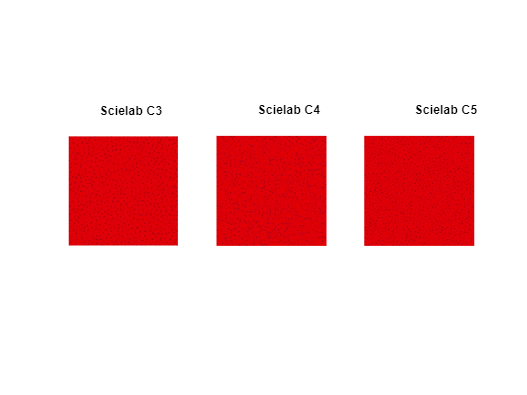


figure
subplot(1,3,1);
imshow(scielab_c3)
title('Scielab C3')
subplot(1,3,2);
imshow(scielab_c4)
title('Scielab C4')
subplot(1,3,3);
imshow(scielab_c5)
title('Scielab C5')


% Display results (the lower the better)
fprintf('Graininess (c1 - Independent halftoning CM): %f\n', graininess_c1);

Graininess (c1 - Independent halftoning CM): 0.051219


fprintf('Graininess (c2 - Dependent halftoning CM): %f\n', graininess_c2);

Graininess (c2 - Dependent halftoning CM): 0.047288


fprintf('Graininess (c3 - Independent halftoning CMY): %f\n', graininess_c3);

Graininess (c3 - Independent halftoning CMY): 0.054971


fprintf('Graininess (c4 - Dependent CMY halftoning): %f\n', graininess_c4);

Graininess (c4 - Dependent CMY halftoning): 0.055377


fprintf('Graininess (c5 - CM Dependent, Y Independent): %f\n', graininess_c5);

Graininess (c5 - CM Dependent, Y Independent): 0.051675



% Answer: 
% According to scilab: C2, C1, C5, C3 & C4
% According to me: Cant see


## 5. SSIM (look at slide 2/3 down Einstein)

Assumes HVS is adapted to extract information and structures from image

% Load grayscale image
peppers_gray = im2double(imread('peppers_gray.tif'));


### 5.a SSIM with Row and Half-Image Distortions

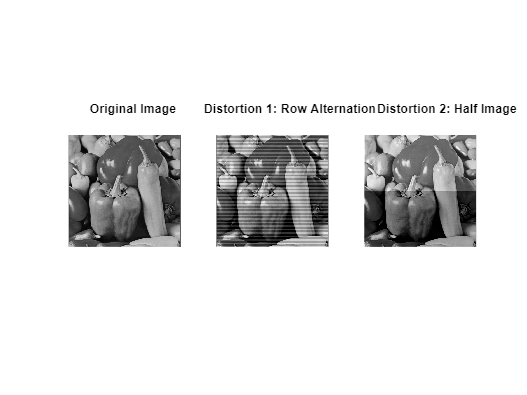

% Create first distortion: alternating rows with +0.1 / -0.1
distorted1 = peppers_gray; 
distorted1(1:2:end, :) = distorted1(1:2:end, :) + 0.1;  % Add 0.1 to odd rows
distorted1(2:2:end, :) = distorted1(2:2:end, :) - 0.1;  % Subtract 0.1 from even rows

% Create second distortion: top half +0.1, bottom half -0.1
distorted2 = peppers_gray;
distorted2(1:end/2, :) = distorted2(1:end/2, :) + 0.1;  % Add 0.1 to top half
distorted2(end/2+1:end, :) = distorted2(end/2+1:end, :) - 0.1;  % Subtract 0.1 from bottom half

% Compute SNR for distortions
snr_distorted1 = snr(peppers_gray, peppers_gray - distorted1);
snr_distorted2 = snr(peppers_gray, peppers_gray - distorted2);

% Compute SSIM for both distortions
[ssim_distorted1, ssim_map1] = ssim(distorted1, peppers_gray);
[ssim_distorted2, ssim_map2] = ssim(distorted2, peppers_gray);

% Display images
figure;
subplot(1,3,1);
imshow(peppers_gray);
title('Original Image');
subplot(1,3,2);
imshow(distorted1);
title('Distortion 1: Row Alternation');
subplot(1,3,3);
imshow(distorted2);
title('Distortion 2: Half Image');

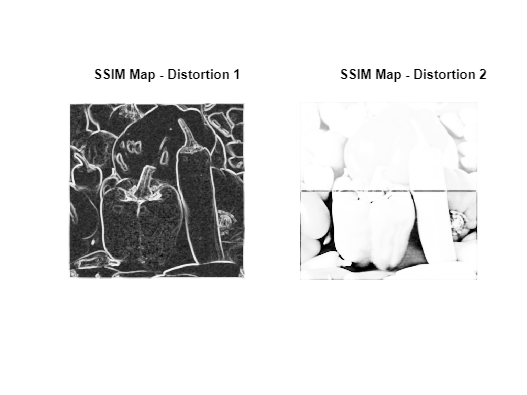


% Display SSIM maps
figure;
subplot(1,2,1);
imshow(ssim_map1, []);
title('SSIM Map - Distortion 1');
subplot(1,2,2);
imshow(ssim_map2, []);
title('SSIM Map - Distortion 2');


% Display results
fprintf('(Distortion 1 - Row Alternation) SNR: %f, SSIM: %f\n', snr_distorted1, ssim_distorted1);

(Distortion 1 - Row Alternation) SNR: 13.430278, SSIM: 0.243545


fprintf('(Distortion 2 - Half Image) SNR: %f, SSIM: %f\n', snr_distorted2, ssim_distorted2);

(Distortion 2 - Half Image) SNR: 13.430278, SSIM: 0.852757



% Answer:
% The reason we get the same SNR is bc values close each other but on
% opposite side of a threshold will be completly diffrent after
% rasterazation. Therefore, the opposite is also true and since both
% distorions cover half, they will get the same value.

% Meanwhile, their SSIM MAP looks completly diffent, one dark and one
% light. Thats bc SSIM is indephendant of the average luminence and contrast

### 5.b SSIM for Noise and Blurring Distortions

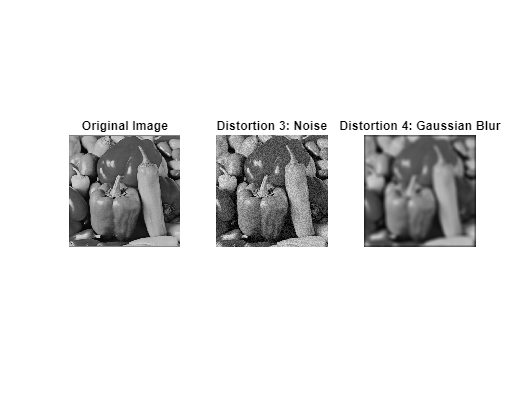

% Generate first distortion: Add random noise
distorted3 = peppers_gray + 0.2 * (rand(size(peppers_gray)) - 0.5);

% Generate second distortion: Apply Gaussian blur
gaussian_filter = fspecial('gauss', 21, 10);
distorted4 = imfilter(peppers_gray, gaussian_filter, 'same');

% Compute SNR for both distortions
snr_distorted3 = snr(peppers_gray, peppers_gray - distorted3);
snr_distorted4 = snr(peppers_gray, peppers_gray - distorted4);

% Compute SSIM for both distortions
[ssim_distorted3, ssim_map3] = ssim(distorted3, peppers_gray);
[ssim_distorted4, ssim_map4] = ssim(distorted4, peppers_gray);

% Display images
figure;
subplot(1,3,1);
imshow(peppers_gray);
title('Original Image');
subplot(1,3,2);
imshow(distorted3);
title('Distortion 3: Noise');
subplot(1,3,3);
imshow(distorted4);
title('Distortion 4: Gaussian Blur');

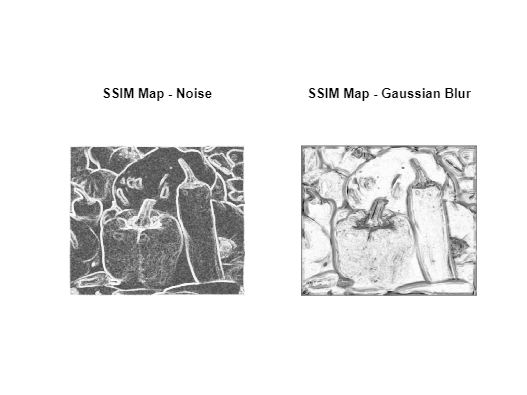


% Display SSIM maps
figure;
subplot(1,2,1);
imshow(ssim_map3, []);
title('SSIM Map - Noise');
subplot(1,2,2);
imshow(ssim_map4, []);
title('SSIM Map - Gaussian Blur');


% Display results
fprintf('(Distortion 3 - Noise) SNR: %f, SSIM: %f\n', snr_distorted3, ssim_distorted3);

(Distortion 3 - Noise) SNR: 18.199140, SSIM: 0.433594


fprintf('(Distortion 4 - Blur) SNR: %f, SSIM: %f\n', snr_distorted4, ssim_distorted4);

(Distortion 4 - Blur) SNR: 14.957707, SSIM: 0.677294



% Answer: In this case SNR are diffrent while SSIM is closer to each other.
% And if we look at SSIM maps, they are inversions of each other (kinda).
% My guess is that they are structuraky similar with smoother transistions
% than shifts in instenuisty.